# Initialize

close all;
clear variables; 
global n_plot
init_FB();

### Observation bandwidth

f_min = 200e9; % lowest frequency
f_max = 460e9; % highest frequency
nF    = 1e4; %number of frequency samples
f     = linspace(f_min,f_max,nF); % frequency  

### Filter-bank properties

Qi          = Inf;%3000; %3300;%Inf; % It can be a vector
sep         = 1/4; %0.133;%0.1625;%1/4;%1/2;%3/4;
Ql_target   = 100;
ThruLineLosses = 0; 
S           = 1; % Oversampling

f0_min      = 220e9;
f0_max      = 2*f0_min;
nFilters    = floor( 1 + log10(f0_max / f0_min) / log10(1 + 1 ./ Ql_target ./ S) );

f0          = zeros(1,nFilters);
f0(1)       = f0_min;

for filter_i=2:nFilters
   f0(filter_i) = f0(filter_i-1) + f0(filter_i-1) * 1 ./ Ql_target ./ S;
end
f0 = sort(f0,'descend');

% TL-Impedances
Z0_KID      = 54.81;
Z0_thru     = 79.04;



singleFilterPlot = nFilters;

% SET SETTINGS
Settings.singleFilterPlot = nFilters; 
Settings.Z0_thru = Z0_thru;
Settings.Z0_KID = Z0_KID;
Settings.Qi = Qi;
Settings.ThruLineLosses = ThruLineLosses;
Settings.sep = sep;
Settings.f0 = f0;
Settings.Ql_target = Ql_target;

### Loop

n_loops = 20;

for iter = 1:n_loops
    n_plot = 0;



### Variances

    %% Ql %%
    Ql_sigma = 0.2 ; % Variance of Ql, normalized to 1
    
    %% f0 %%
    f0_sigma = 0;%0.27;% .* Ql_target ./ 500; % Relative variance of f0 (df), normalized to 1. 
    f0_drift = 0; % linear drift of f0
    f0_offset = 0; % additive offset of f0
    
    % Lower bound on Ql_scattered, based on analysis of Deshima II by Akira
    Ql_min_thresh = -1.5 .* Ql_target .* Ql_sigma;
    
    
    
    num_elem = 4; 
    Ql_variance = zeros(num_elem,nFilters);
    f0_variance = zeros(num_elem,nFilters);
    
    interFilterVariance = true;
    
    
    if interFilterVariance
        
%         Ql_sigma = Ql_sigma ./ sqrt(2);
%         f0_sigma = f0_sigma ./ sqrt(2);
    
        for i_elem = 1:num_elem %#ok<*UNRCH> 
            
            %%%% Scattered design parameters %%%%
            Ql_variance(i_elem,:) = Ql_target .* Ql_sigma .* randn(1,nFilters);
            Ql_variance(i_elem,Ql_variance(i_elem,:) < Ql_min_thresh) = Ql_min_thresh;
            df = f0 ./ Ql_target;
            f0_variance(i_elem,:) = df .* f0_sigma .* randn(1,nFilters);
        end
    else
        
        %%%% Scattered design parameters %%%%
        Ql_variance = repmat(Ql_target .* Ql_sigma .* randn(1,nFilters),4,1);
        Ql_variance(Ql_variance < Ql_min_thresh) = Ql_min_thresh;
        df = f0 ./ Ql_target;
        f0_variance = repmat(df .* f0_sigma .* randn(1,nFilters),4,1);
    end
    
    Settings.f0_variance = f0_variance;
    Settings.Ql_variance = Ql_variance;

# Filterbanks

## Directional filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceDirectionalFilter(f,Settings);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 4.620191 seconds


Section took 5.079508 seconds


Section took 4.765817 seconds


Section took 4.827690 seconds


Section took 4.940691 seconds


Section took 5.054738 seconds


Section took 4.753393 seconds


Section took 4.735045 seconds


Section took 5.389411 seconds


Section took 5.050807 seconds


Section took 4.965645 seconds


Section took 4.766406 seconds


Section took 5.292692 seconds


Section took 4.884067 seconds


Section took 4.701584 seconds


Section took 4.647655 seconds


Section took 4.625689 seconds


Section took 4.654723 seconds


Section took 4.891123 seconds


Section took 4.607694 seconds


    
%     showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_thru,Z0_KID,Ql_target)
    Data_dir(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);

Section took 1.546175 seconds
Usable Spectral Fraction old = 0.93
Usable Spectral Fraction half mean envelope = 0.83
Section took 0.525109 seconds


Section took 1.439547 seconds
Usable Spectral Fraction old = 0.90
Usable Spectral Fraction half mean envelope = 0.83
Section took 0.494120 seconds


Section took 1.479778 seconds
Usable Spectral Fraction old = 0.93
Usable Spectral Fraction half mean envelope = 0.83
Section took 0.481329 seconds


Section took 1.610734 seconds
Usable Spectral Fraction old = 0.91
Usable Spectral Fraction half mean envelope = 0.80
Section took 0.676034 seconds


Section took 1.517324 seconds
Usable Spectral Fraction old = 0.94
Usable Spectral Fraction half mean envelope = 0.83
Section took 0.519775 seconds


Section took 1.626818 seconds
Usable Spectral Fraction old = 0.91
Usable Spectral Fraction half mean envelope = 0.83
Section took 0.522459 seconds


Section took 1.447316 seconds
Usable Spectral Fraction old = 0.89
Usable Spectral Fraction half mean envelope = 0.83
Section took 0.481002 seconds


Section took 1.460751 seconds
Usable Spectral Fraction old = 0.89
Usable Spectral Fraction half mean envelope = 0.82
Section took 0.498810 seconds


Section took 1.507522 seconds
Usable Spectral Fraction old = 0.93
Usable Spectral Fraction half mean envelope = 0.83
Section took 0.511749 seconds


Section took 1.711878 seconds
Usable Spectral Fraction old = 0.94
Usable Spectral Fraction half mean envelope = 0.81
Section took 0.576463 seconds


Section took 1.490207 seconds
Usable Spectral Fraction old = 0.92
Usable Spectral Fraction half mean envelope = 0.84
Section took 0.498481 seconds


Section took 1.453112 seconds
Usable Spectral Fraction old = 0.93
Usable Spectral Fraction half mean envelope = 0.85
Section took 0.486280 seconds


Section took 1.507636 seconds
Usable Spectral Fraction old = 0.94
Usable Spectral Fraction half mean envelope = 0.85
Section took 0.577812 seconds


Section took 1.483300 seconds
Usable Spectral Fraction old = 0.92
Usable Spectral Fraction half mean envelope = 0.82
Section took 0.499772 seconds


Section took 1.435156 seconds
Usable Spectral Fraction old = 0.95
Usable Spectral Fraction half mean envelope = 0.83
Section took 0.481057 seconds


Section took 1.430453 seconds
Usable Spectral Fraction old = 0.91
Usable Spectral Fraction half mean envelope = 0.83
Section took 0.466733 seconds


Section took 1.435221 seconds
Usable Spectral Fraction old = 0.94
Usable Spectral Fraction half mean envelope = 0.84
Section took 0.482694 seconds


Section took 1.456375 seconds
Usable Spectral Fraction old = 0.92
Usable Spectral Fraction half mean envelope = 0.83
Section took 0.482243 seconds


Section took 1.456807 seconds
Usable Spectral Fraction old = 0.93
Usable Spectral Fraction half mean envelope = 0.84
Section took 0.508424 seconds


Section took 1.411128 seconds
Usable Spectral Fraction old = 0.91
Usable Spectral Fraction half mean envelope = 0.85
Section took 0.493537 seconds


    % % % showDimensions(f,f0,l_thru)

## Reflector filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceReflectorFilter(f,Settings);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 2.684439 seconds


Section took 3.001675 seconds


Section took 2.680172 seconds


Section took 2.985526 seconds


Section took 2.827494 seconds


Section took 2.786079 seconds


Section took 2.716770 seconds


Section took 2.681475 seconds


Section took 2.791701 seconds


Section took 3.446871 seconds


Section took 2.765432 seconds


Section took 2.744494 seconds


Section took 2.853639 seconds


Section took 2.582601 seconds


Section took 2.691455 seconds


Section took 2.669867 seconds


Section took 2.661017 seconds


Section took 2.757572 seconds


Section took 2.663950 seconds


Section took 2.626720 seconds


    
%     showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_thru,Z0_KID,Ql_target)
    Data_refl(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);

Section took 1.336386 seconds
Usable Spectral Fraction old = 0.83
Usable Spectral Fraction half mean envelope = 0.74
Section took 0.498025 seconds


Section took 1.528020 seconds
Usable Spectral Fraction old = 0.87
Usable Spectral Fraction half mean envelope = 0.72
Section took 0.539408 seconds


Section took 1.331629 seconds
Usable Spectral Fraction old = 0.72
Usable Spectral Fraction half mean envelope = 0.77
Section took 0.499566 seconds


Section took 1.386039 seconds
Usable Spectral Fraction old = 0.77
Usable Spectral Fraction half mean envelope = 0.78
Section took 0.603260 seconds


Section took 1.433114 seconds
Usable Spectral Fraction old = 0.86
Usable Spectral Fraction half mean envelope = 0.80
Section took 0.556570 seconds


Section took 1.350437 seconds
Usable Spectral Fraction old = 0.86
Usable Spectral Fraction half mean envelope = 0.76
Section took 0.548698 seconds


Section took 1.312404 seconds
Usable Spectral Fraction old = 0.61
Usable Spectral Fraction half mean envelope = 0.72
Section took 0.486405 seconds


Section took 1.368442 seconds
Usable Spectral Fraction old = 0.76
Usable Spectral Fraction half mean envelope = 0.75
Section took 0.482153 seconds


Section took 1.422335 seconds
Usable Spectral Fraction old = 0.78
Usable Spectral Fraction half mean envelope = 0.77
Section took 0.475043 seconds


Section took 1.486673 seconds
Usable Spectral Fraction old = 0.74
Usable Spectral Fraction half mean envelope = 0.74
Section took 0.554329 seconds


Section took 1.383625 seconds
Usable Spectral Fraction old = 0.80
Usable Spectral Fraction half mean envelope = 0.77
Section took 0.540737 seconds


Section took 1.331866 seconds
Usable Spectral Fraction old = 0.84
Usable Spectral Fraction half mean envelope = 0.81
Section took 0.489583 seconds


Section took 1.347374 seconds
Usable Spectral Fraction old = 0.77
Usable Spectral Fraction half mean envelope = 0.78
Section took 0.514936 seconds


Section took 1.299994 seconds
Usable Spectral Fraction old = 0.75
Usable Spectral Fraction half mean envelope = 0.72
Section took 0.493360 seconds


Section took 1.304261 seconds
Usable Spectral Fraction old = 0.69
Usable Spectral Fraction half mean envelope = 0.75
Section took 0.486093 seconds


Section took 1.304536 seconds
Usable Spectral Fraction old = 0.77
Usable Spectral Fraction half mean envelope = 0.75
Section took 0.492416 seconds


Section took 1.297206 seconds
Usable Spectral Fraction old = 0.82
Usable Spectral Fraction half mean envelope = 0.72
Section took 0.492247 seconds


Section took 1.498400 seconds
Usable Spectral Fraction old = 0.77
Usable Spectral Fraction half mean envelope = 0.74
Section took 0.492040 seconds


Section took 1.330828 seconds
Usable Spectral Fraction old = 0.80
Usable Spectral Fraction half mean envelope = 0.76
Section took 0.471947 seconds


Section took 1.301635 seconds
Usable Spectral Fraction old = 0.76
Usable Spectral Fraction half mean envelope = 0.77
Section took 0.461759 seconds


    % % % % showDimensions(f,f0,l_thru)

## Manifold filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceManifoldFilter(f,Settings);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 2.086603 seconds


Section took 2.053480 seconds


Section took 2.194247 seconds


Section took 2.367284 seconds


Section took 2.387394 seconds


Section took 2.092393 seconds


Section took 2.069574 seconds


Section took 2.215014 seconds


Section took 2.128471 seconds


Section took 2.347644 seconds


Section took 2.144727 seconds


Section took 2.017256 seconds


Section took 2.152136 seconds


Section took 2.058988 seconds


Section took 2.046534 seconds


Section took 2.043278 seconds


Section took 2.065267 seconds


Section took 2.099938 seconds


Section took 2.064074 seconds


Section took 2.028859 seconds


    
%     showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_thru,Z0_KID,Ql_target)
    Data_man(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);

Section took 1.328305 seconds
Usable Spectral Fraction old = 0.78
Usable Spectral Fraction half mean envelope = 0.74
Section took 0.478632 seconds


Section took 1.331614 seconds
Usable Spectral Fraction old = 0.81
Usable Spectral Fraction half mean envelope = 0.73
Section took 0.463613 seconds


Section took 1.329713 seconds
Usable Spectral Fraction old = 0.76
Usable Spectral Fraction half mean envelope = 0.73
Section took 0.478363 seconds


Section took 1.382172 seconds
Usable Spectral Fraction old = 0.77
Usable Spectral Fraction half mean envelope = 0.73
Section took 0.502524 seconds


Section took 1.599098 seconds
Usable Spectral Fraction old = 0.79
Usable Spectral Fraction half mean envelope = 0.72
Section took 0.560007 seconds


Section took 1.363764 seconds
Usable Spectral Fraction old = 0.81
Usable Spectral Fraction half mean envelope = 0.75
Section took 0.492291 seconds


Section took 1.325634 seconds
Usable Spectral Fraction old = 0.75
Usable Spectral Fraction half mean envelope = 0.74
Section took 0.491701 seconds


Section took 1.381024 seconds
Usable Spectral Fraction old = 0.83
Usable Spectral Fraction half mean envelope = 0.76
Section took 0.504341 seconds


Section took 1.342578 seconds
Usable Spectral Fraction old = 0.82
Usable Spectral Fraction half mean envelope = 0.73
Section took 0.453834 seconds


Section took 1.493956 seconds
Usable Spectral Fraction old = 0.78
Usable Spectral Fraction half mean envelope = 0.72
Section took 0.506481 seconds


Section took 1.498518 seconds
Usable Spectral Fraction old = 0.86
Usable Spectral Fraction half mean envelope = 0.75
Section took 0.501225 seconds


Section took 1.306836 seconds
Usable Spectral Fraction old = 0.83
Usable Spectral Fraction half mean envelope = 0.75
Section took 0.538131 seconds


Section took 1.339845 seconds
Usable Spectral Fraction old = 0.80
Usable Spectral Fraction half mean envelope = 0.74
Section took 0.483381 seconds


Section took 1.304350 seconds
Usable Spectral Fraction old = 0.82
Usable Spectral Fraction half mean envelope = 0.73
Section took 0.493941 seconds


Section took 1.290542 seconds
Usable Spectral Fraction old = 0.79
Usable Spectral Fraction half mean envelope = 0.73
Section took 0.486008 seconds


Section took 1.299666 seconds
Usable Spectral Fraction old = 0.78
Usable Spectral Fraction half mean envelope = 0.74
Section took 0.493278 seconds


Section took 1.295432 seconds
Usable Spectral Fraction old = 0.84
Usable Spectral Fraction half mean envelope = 0.75
Section took 0.484451 seconds


Section took 1.331445 seconds
Usable Spectral Fraction old = 0.77
Usable Spectral Fraction half mean envelope = 0.74
Section took 0.512622 seconds


Section took 1.311390 seconds
Usable Spectral Fraction old = 0.80
Usable Spectral Fraction half mean envelope = 0.74
Section took 0.452151 seconds


Section took 1.304715 seconds
Usable Spectral Fraction old = 0.79
Usable Spectral Fraction half mean envelope = 0.71
Section took 0.470523 seconds


    % % showDimensions(f,f0,l_thru)
    
end

## Plotting

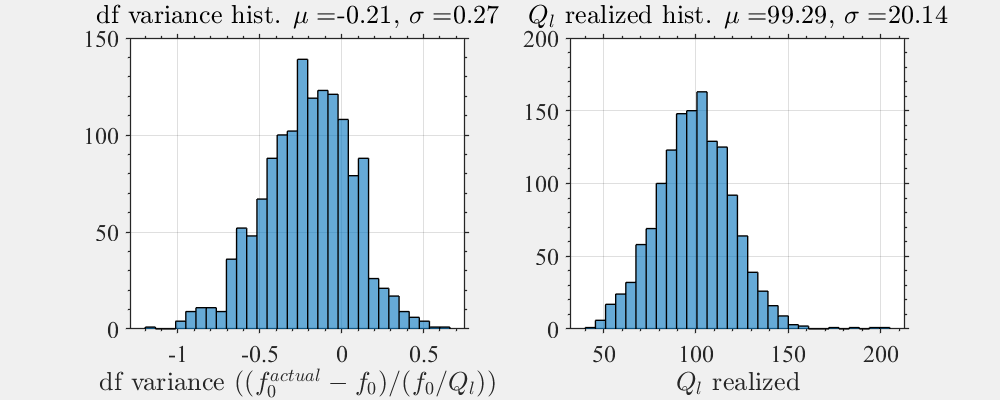

close all; 
clear functions; %#ok<CLFUNC>
n_plot = 1;
showFilterBank(f,Data_dir); 
% showMetrics(f,Ql_target,Data_dir);

Stats_dir = calcStatistics(f0,Ql_target,Data_dir);
showStatistics(f,Data_dir,Stats_dir);

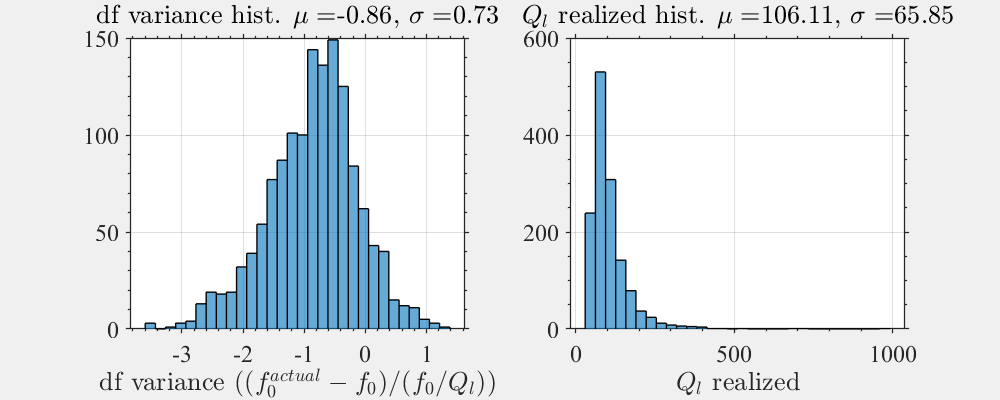


n_plot = 2;
showFilterBank(f,Data_refl);
% showMetrics(f,Ql_target,Data_refl);

Stats_refl = calcStatistics(f0,Ql_target,Data_refl);
showStatistics(f,Data_refl,Stats_refl);

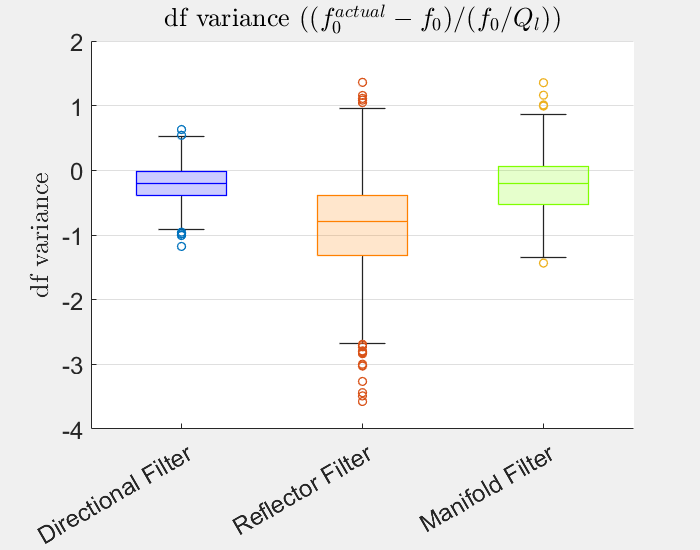

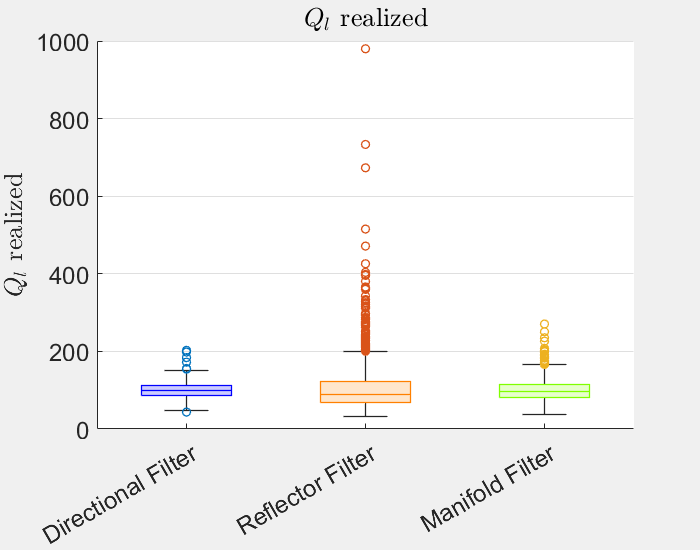

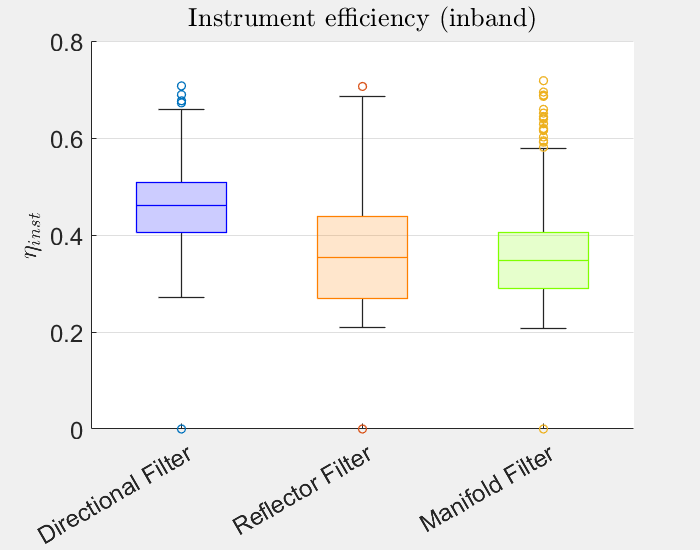

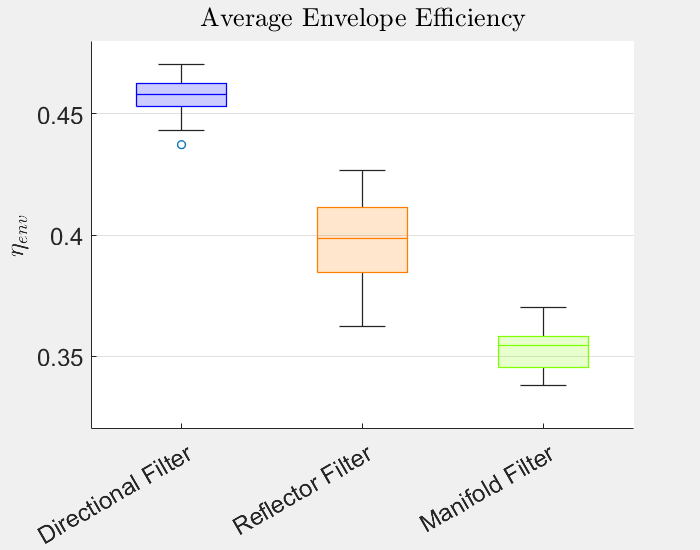

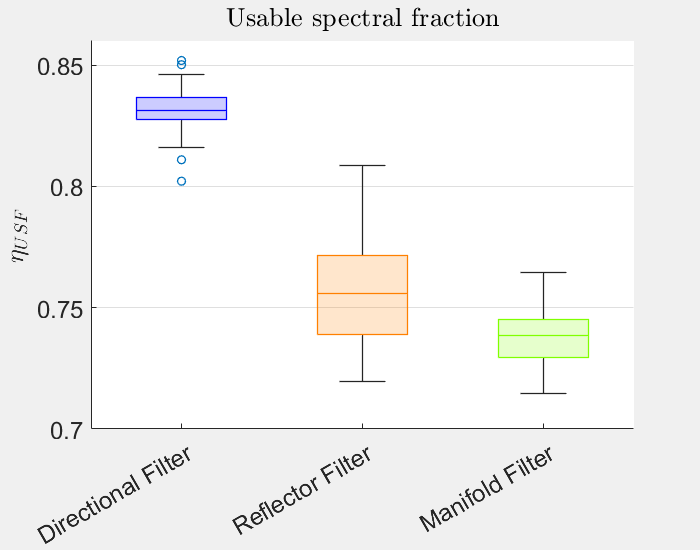

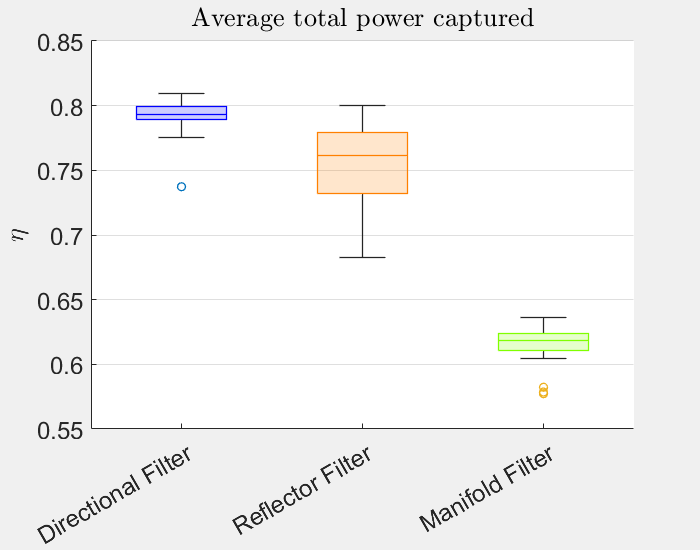

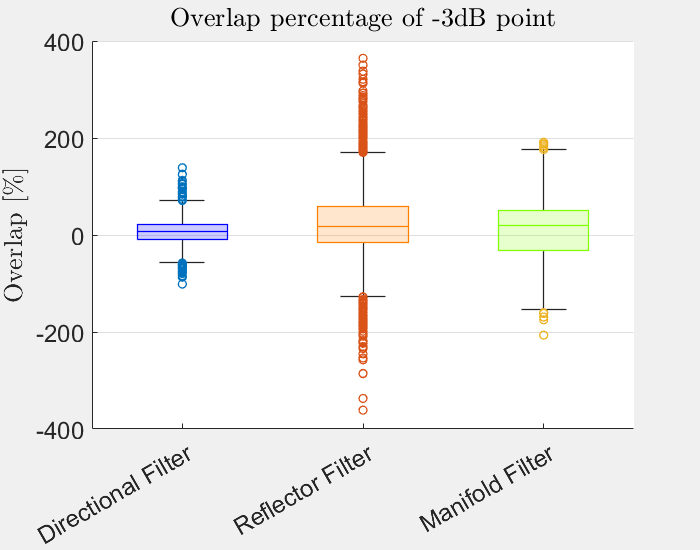

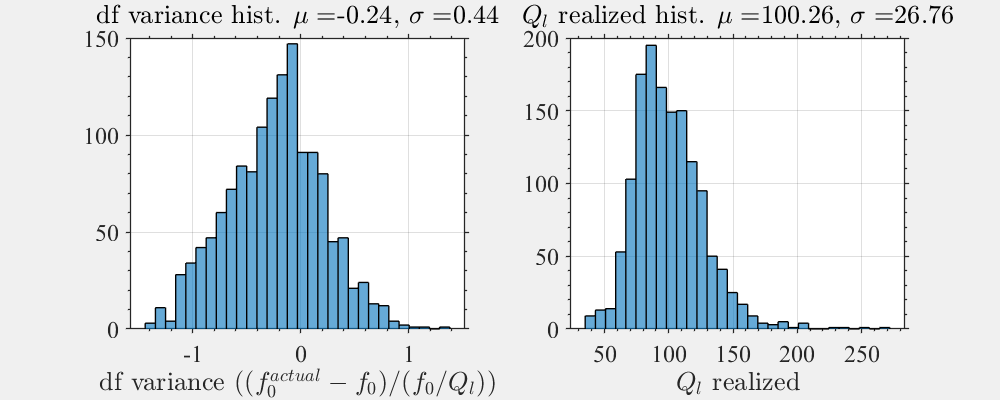



n_plot = 3;
showFilterBank(f,Data_man);
% showMetrics(f,Ql_target,Data_man);

Stats_man = calcStatistics(f0,Ql_target,Data_man);
showStatistics(f,Data_man,Stats_man);

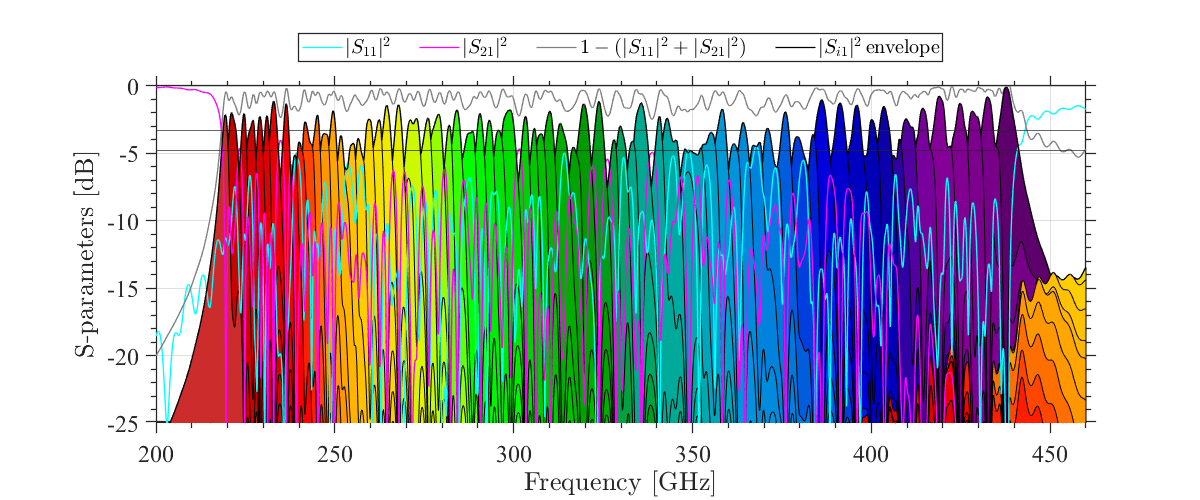

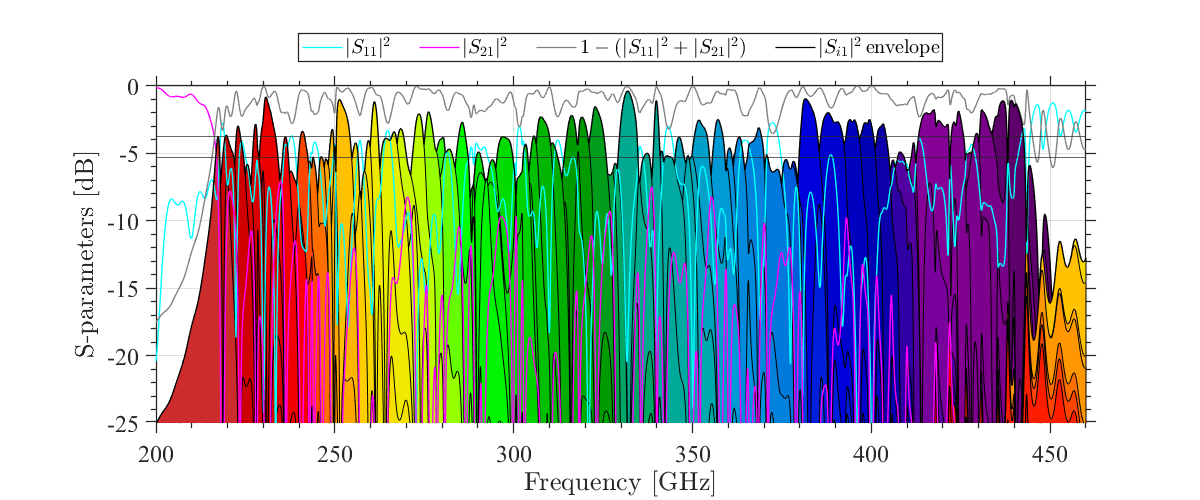

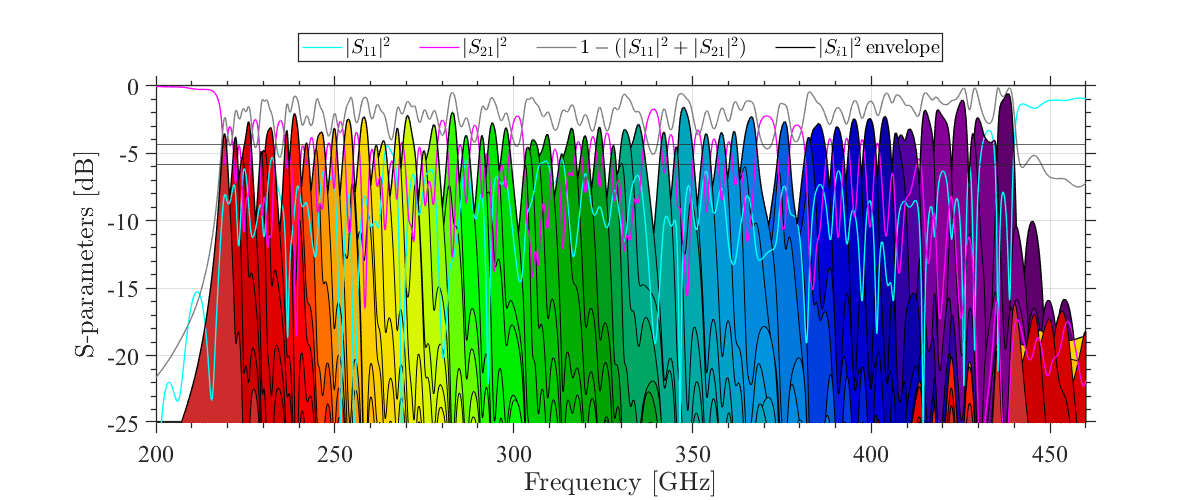



formatPlotting();